# Terahertz band in Body-communication Simulator 

## Description

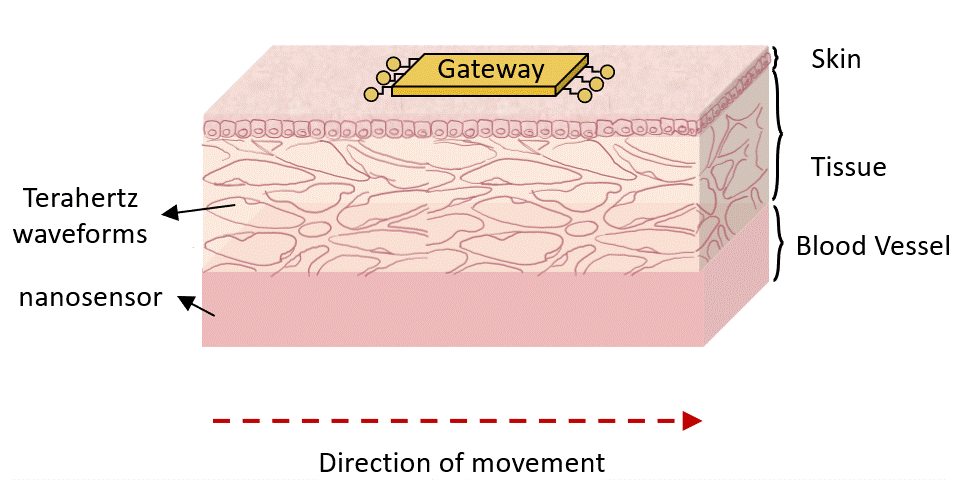

Figure 1: System model.

This code aims to simulate the communication performance between traveling nanosensors in the blood flow and external wearables, as depicted in Fig. 1. The communication is produced in the terahertz band. It takes into account the impact of mobility as the Doppler effect. The modulation format is the binary phase shift keying (BPSK). The communication channel between the nanosensor and the Gateway is modeled according to the equation [1]:

$r(t)=g_d\,s(t-\tau_d)\,e^{j2\pi\nu t}$, (1)

where $g_d$ is the channel gain, $\tau_d$ is the propagation delay, and $\nu$ is the Doppler frequency as:

$\nu=v\cos(\phi)\frac{f_c}{c_0}$. (2)

In Eq. (2) $v$ is the velocity of the nanosensor, $c_0$ is the propagation speed of the waveform (speed of light), $f_c$ is the carrier frequency, and $\phi$ is the angle of arrival of the wave relative to the direction of motion of the nanosensor, as depicted in Fig. 2.

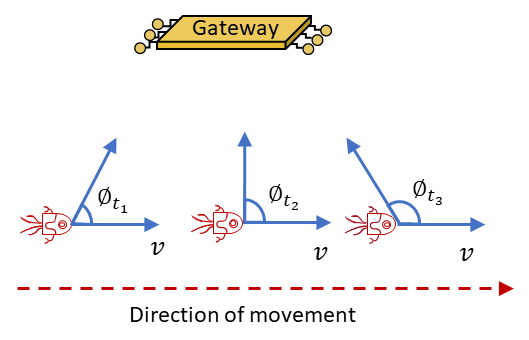

Figure 2: Description of the angle of emissions from the nanosensors along the vessel.

This interface provides adjustable parameters regarding the center frequency for communications, and distance parameters such as the tissue and vessel thickness, as well as the communication range given by the distance between the nanosensor and the Gateway, see Fig. 3. The communication range is always between the minimum and maximum distance lengths.

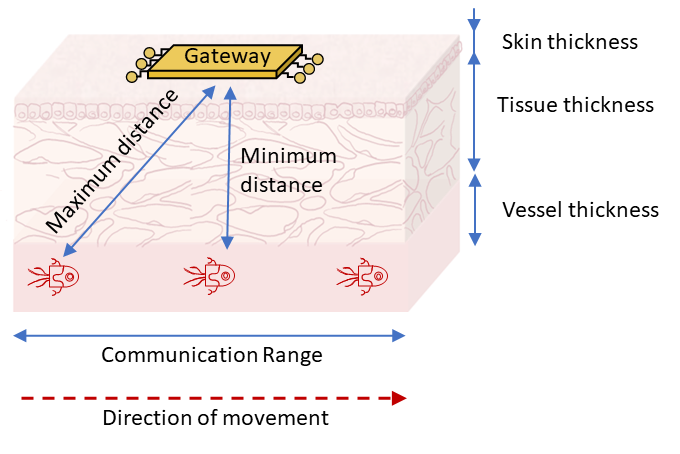

Figure 3: Representation of distances in the tissue.

Outputs are provided regarding the communication scheme as:

- The channel gain versus time: $g_d$ in (1). This is evaluated using the reference in [2].

- The Doppler frequency: $\nu$ according to (2).

- The achievable bit error rate (BER) versus time.

#### How to run this code

This code runs directly when clicking the run button or updating the parameters below. This code calls to functions implemented in C/C++ (see terahertz.c and terahertz.h). The functions defined in these two files simulate and evaluate the communication system. To re-build these functions, it is needed to install the [MinGW-w64 Compiler (free)](https://www.mathworks.com/help/matlab/matlab_external/install-mingw-support-package.html) and to uncomment lines in the compiling block below.

## Parameters

#### **Waveform parameters**

**Carrier frequency:**

 Freq_THz=2.2*10^12;

**Waveform**

waveform="BPSK";

**Sampling:**

sampling_time=10^(-3);

#### **Spatial Parameters**

**Tissue and Vessel Thickness in**$\mu$**m, see Fig. 3: **

Skin_thickness =76*10^(-6); %Epidermis, further details in [3]
Tissue_thickness=1022*10^(-6);%Dermis, further details in [4]
Vessel_thickness= 200*10^(-6);%Dermis, further details in [5]

**Communication range (**$\mu$**m):**

Comm_dist=5277*10^(-6);

**Blood speed (m/s):**

blood_speed=0.44*10^(-1); %Blood speed according to [6] (aorta: 0.2 m/s, arteries: 0.1 m/s, veins: 0.03 m/s)

## **Compiling the functions in C code**

%% Uncomment the next three lines when editing the
%% terahertz.c or terahertz.h files
%% choosing the C++ compiler, if not previously installed at the local PC, follow steps to install MinGW-w64 Compiler in Matlab (free) https://www.mathworks.com/help/matlab/matlab_external/install-mingw-support-package.html.
mex -setup C++ 

MEX configured to use 'MinGW64 Compiler (C++)' for C++ language compilation.


%% compiling the C code for the path loss
codegen -config:lib pathLoss -args {0,0,0,0,0}

Code generation successful.



codegen -config:mex pathLoss codegen\lib\pathLoss\pathLoss.lib -args {0,0,0,0,0}

Code generation successful.



## **Communication Performance**

#### **Channel gain**

%running the C code
pathLoss_mex(Freq_THz,Comm_dist,Skin_thickness,Tissue_thickness,Vessel_thickness)

ans = 276.7501

## Parameter sweep plots

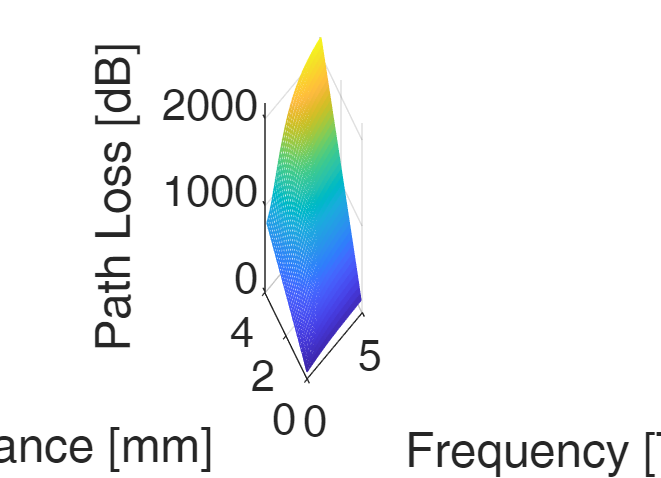

%frequency in the terahertz band
Freq_THz_vector=(0.1:0.1:5)*10^12;
%Thickness of Skin, Tissue, and Vessel, the variability is introduced in
%the Tissue thickness
Skin_thickness = 76*10^(-6);
Tissue_thickness = 1022*10^(-6);
Vessel_thickness = 200*10^(-6);

Comm_dist_vector=(Skin_thickness+Tissue_thickness+Vessel_thickness):10^(-3):4*10^(-2);

%pre-allocating the channel gain matrix
channelLoss_matrix_dB=zeros(length(Freq_THz_vector),length(Comm_dist_vector));
%computing the channel gain
for f=1:length(Freq_THz_vector)
    for dist=1:length(Comm_dist_vector)
        %calling to the pre-compiled C function
        channelLoss_matrix_dB(f,dist)=pathLoss_mex(Freq_THz_vector(f),Comm_dist_vector(dist),Skin_thickness,Tissue_thickness,Vessel_thickness);
    end
end

%plotting
fontsize=24;
[F,D]=meshgrid(Freq_THz_vector/10^(12),Comm_dist_vector/10^(-2));
mesh(F,D,channelLoss_matrix_dB');
xlabel('Frequency [THz]');
ylabel('Distance [mm]');
zlabel('Path Loss [dB]');
set(gca,'FontSize',fontsize);

## **References**

[1] G. Matz and F. Hlawatsch, “Fundamentals of Time-Varying Communication Channels,” in Wireless Communications Over Rapidly Time-Varying Channels, F. Hlawatsch and G. Matz, Eds., Elsevier, 2011, pp. 1–63.

[2] J. Simonjan, B. D. Unluturk and I. F. Akyildiz, "In-Body Bionanosensor Localization for Anomaly Detection via Inertial Positioning and THz Backscattering Communication," in IEEE Transactions on NanoBioscience, vol. 21, no. 2, pp. 216-225, April 2022, doi: 10.1109/TNB.2021.3123972.

[3] G. Piro, P. Bia, G. Boggia, D. Caratelli, L.A. Grieco, L. Mescia, "Terahertz electromagnetic field propagation in human tissues: A study on communication capabilities," Nano Communication Networks, Volume 10, 2016, Pages 51-59, ISSN 1878-7789, [https://doi.org/10.1016/j.nancom.2016.07.010.](https://doi.org/10.1016/j.nancom.2016.07.010.)

[4] P. Oltulu, B. Ince, N. Kokbudak, F. Kılıc¸ ¨ et al., “Measurement of epidermis, dermis, and total skin thicknesses from six different body regions with a new ethical histometric technique,” Turk Plastik, Rekonstr ¨ uktif ve ¨ Estetik Cerrahi Dergisi (Turk J Plast Surg), vol. 26, no. 2, pp. 56–61, 2018. DOI: 10.4103/tjps.TJPS_2_17

[5] M. Fruchard, L. Arcese, and E. Courtial, “Estimation of the blood velocity for nanorobotics,” IEEE Transactions on Robotics, vol. 30, no. 1, pp. 93–102, 2013.

[6] A. C. Guyton and M. E. Hall, Guyton and Hall Textbook of Medical Physiology, 14th ed. Elsevier, 2015.